# This program is used to simulate regular grids of connect springs with free rotation

## generate geometry

clear;
dim = [10 10]; 
[position,connectivity, springs] = generategeometry_COPY("triangle", dim(1), dim(2), 1);
% mymodel = generategeometry("triangle",dim(1),dim(2),1, "edges"); 

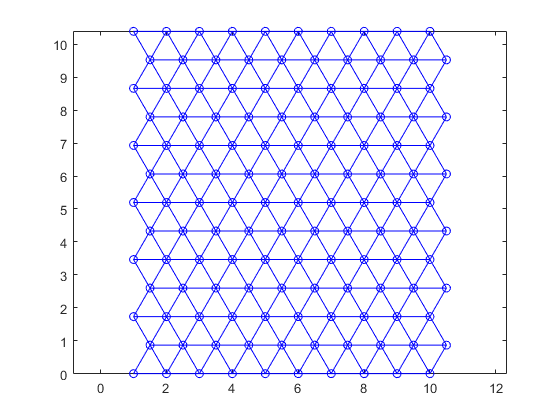

%[position,connectivity] = generaterandom(50,50,1,1.5);                     % not made yet

## Intialize spring length and anchored points

mymodel = initializemymodel(position,connectivity,springs,"edges"); 

## Test stiffness at a point

tic
[AMRstiffnesses, newModel2] = amrliketest_COPY(0.5, 0, 5, 5, mymodel, "linear");
toc

## display model

displaymymodel(mymodel,"simple");
% displaymymodel(mymodel2,"strain");                                         % not sure what it does, just ported over from old code

## change intial length

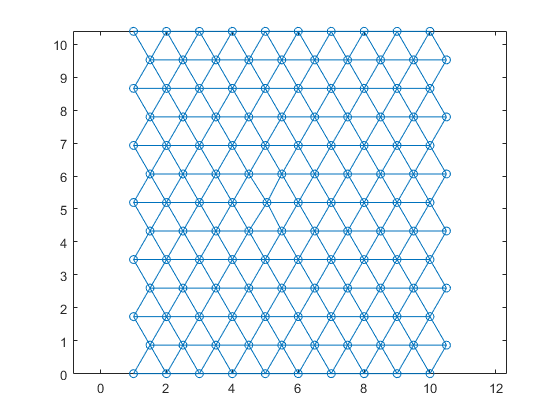

%changespringlengthrandom();                                                % not made yet 
mymodel2 = mymodel; 
OGpos = mymodel.position;
parameters = [10 10 1.5 0.5];

for scans = 1:20
    mymodel2 = photocrosslinkregion(mymodel2, "circle", parameters, 0.05, true, 40, "linear", stiff_idx); 
%     d = zeros(scans, length(OGpos)); 
%     mag = zeros(scans, length(OGpos)); 
%     newPos = mymodel2.position; 
%     dis = newPos - OGpos; 
%     for i = 1:length(position)-1
%         d(scans, i) = hypot(position(i, 1) - parameters(1), position(i, 2) - parameters(2)); 
%         mag(scans, i) = hypot(dis(i,1), dis(i,2)); 
%     end
end
save("figureVals", "d", "mag")
for e = 1:size(d,1)
    figure
    rectangle('Position',[0 0 parameters(3) 5],'FaceColor','w','EdgeColor','k','LineStyle', '--')
    hold on
    % plot(d(e,:), mag(e,:))
    scatter(d(e,:), mag(e,:))
    ylim([0 5])
    xlabel('Distance from center of circle')
    ylabel('estimated optical flow in \mum (mean and SD)')
    % text(55, 4.5, scans + " scans", 'FontSize', 16)
    hold off
    F(scans) = getframe(gcf);     
%     displaydisplacement(mymodel,mymodel2, dim, parameters)
end
writerObj = VideoWriter('crosslinking-graph.avi');
writerObj.FrameRate = 5;
open(writerObj)
for i = 1:length(F)
    frame = F(i);
    writeVideo(writerObj, frame);
end
close(writerObj)
% displacement between current vs @ scan 0 or between each time point?
% steady state before next run

## save the current model

userinput = input('Enter file name: ' , 's');                               % pick a good name
save(userinput,'mymodel')